#  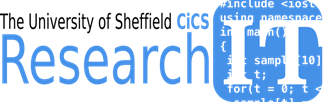                                      

# **Visualisation with Matlab**

## Outline

- overview

- program control structures

- scripts and functions

- Importing Data

- Data Types

# Overview

- course material

- matlab environment

- getting help

- vectors and matrices

- array indexing and operations

- simple plotting

# Review of Basic Graphics

# Review of Basic Graphics

•Powerful 2D and 3D graphics features are available.

•Graphics is built upon a collection of objects whose properties can be altered to change the appearance of graphs.

•Graphs may be drawn by using the low-level graphics primitives alone but there are usually higher level functions available for most of the common graphics needs.    

## Figure Window

•Any graphics command will normally use the current figure window ‘if there is one’ or open up a new figure window ‘if there is not one already’ , and will create the plots within that window.

•It is always possible to open a new graphics window by using the figurecommand. Figure windows can later be closed by using the closecommand or cleared by using the clfcommand. 

•When dealing with multiple figure windows, a better control can be applied by using  handles.

x=-pi:2*pi/20:pi

x =    -3.1416   -2.8274   -2.5133   -2.1991   -1.8850   -1.5708   -1.2566   -0.9425   -0.6283   -0.3142         0    0.3142    0.6283    0.9425    1.2566    1.5708    1.8850    2.1991    2.5133    2.8274    3.1416


y1=sin(-pi:2*pi/20:pi);
y2=cos(-pi:2*pi/20:pi);
y3=y1+y2;
y=y3.^2

y =     1.0000    1.5878    1.9511    1.9511    1.5878    1.0000    0.4122    0.0489    0.0489    0.4122    1.0000    1.5878    1.9511    1.9511    1.5878    1.0000    0.4122    0.0489    0.0489    0.4122    1.0000


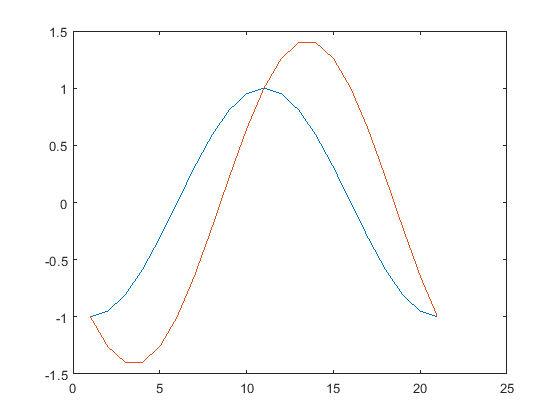

h1 = figure;     
plot(y1);
h2 = figure;     
plot(y2) ; 
hold on ; 
plot(y3) 

close (h1) ; 
clf(h2) ; 


## Plot Control Commands

•Figure  : This command creates a new graphics window. Multiple figure windows will happily coexist. Only one of the figures will have the focus for drawing.

•Hold : Each graph is usually drawn into a clean window, by deleting the current display area. The hold command will over-ride this behavior and draw the new graph over the existing one.

## Commands for Plotting

plot ( x/y) plotting. loglog, semilogx and semilogyare variations of the plot command.

title : adds title to a plot

xlabel , ylabel : add x and y axis labels

text , gtext : to add arbitrary text on a graph.

grid : adds grid-lines

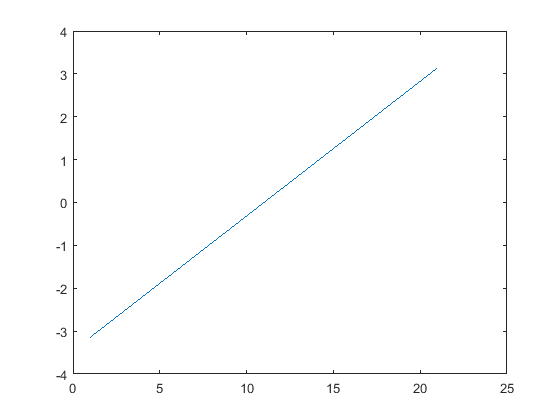

clear gcf; %clear the current graphics figure
plot(x)  % plots x versus its index. If x is a matrix plots each column as a different series on the same axis. 
plot(x,y) % plots x versus y
plot(x,y,'rx') %---> as above but also specify the line colour and/or style.
               % Where the string is one or more characters which indicate the line_colour and optionally the line_type to use.
                   %the line_colour indicator can be one of  c,m,y,r,g,b or w.  
                   %the line_type can be one of   o,+,* -,: ,-. or -- .  
y3=y1+y2;
y=y3.^2
plot(x,y1,x,y2,x,y3)   % → plot y1,y2 and y3 using the same x axis and   
                       % with same scaling.

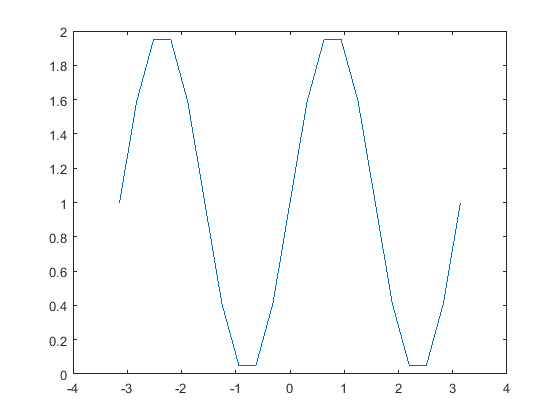

plotyy(x,y1,x,y2)       %→ plot y1 and y2 against x on same plot but use different scales for each graph. 

•Subplot : This command will divide the current graphics figure into multiple panels  and allow you to draw a different graphs in each panel.

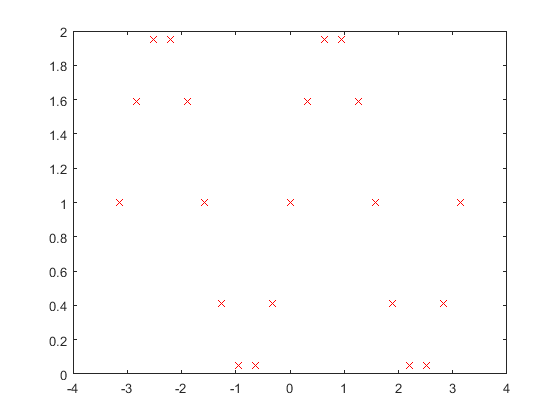

subplot(2,2,1) ; plot(y1) 

subplot(2,2,2) ; plot(y2)
subplot(2,2,3) ; plot(y3) 
subplot(2,2,4) ; plot(x) 
hold off

•Bar and area graphs 

–bar, barh

–bar3 , bar3h

–area

•Pie charts

–pie

•Histograms

–hist , histc

# Importing Data and Pre-Processing Data

Inspect a set of data

subplot(1,1,1)

y =     1.0000    1.5878    1.9511    1.9511    1.5878    1.0000    0.4122    0.0489    0.0489    0.4122    1.0000    1.5878    1.9511    1.9511    1.5878    1.0000    0.4122    0.0489    0.0489    0.4122    1.0000


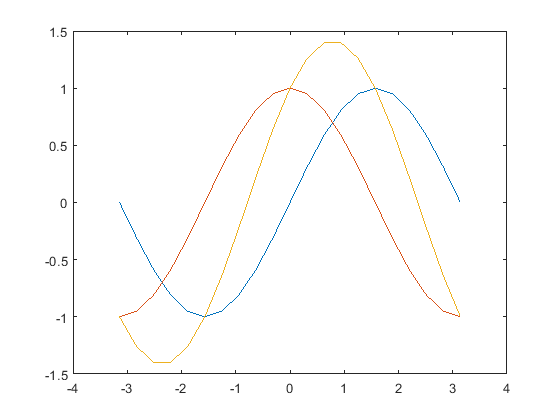

plot(x)

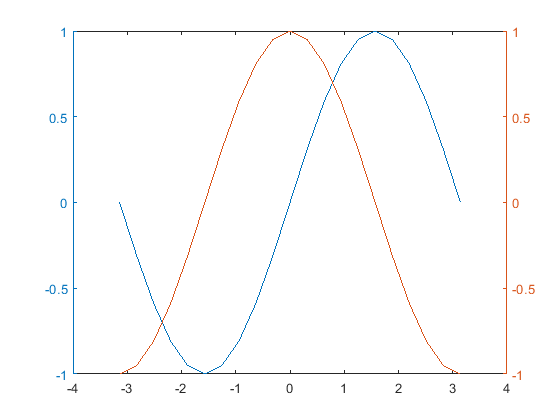

clear gcf


edit ..\data\hurricaneData1990s.txt




Import data set and show scatter plot

hurrs=readtable('..\data\hurricaneData1990s.txt')
scatter(hurrs.Pressure,hurrs.Windspeed)

Import data set with header lines

hurrs2=readtable('..\data\hurricaneData1990s-v2.txt','HeaderLines',5)
scatter(hurrs2.Number,hurrs2.Windspeed)

import data and skip lines with particular format ignore comment lines specify format

can alos specify particular delimeters

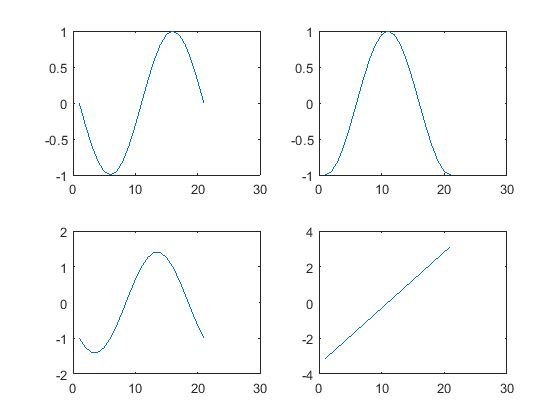

hurrs3=readtable('..\data\hurricaneData1990s-v3.txt','CommentStyle','##')

scatter(hurrs3.Number,hurrs3.Windspeed)
x = readtable('..\data\hurricaneData1990s-v2.txt',...
      'Delimiter',',\t',...
      'HeaderLines',5);
  hurrs3

%    sz=size(hurrs3);
%   a=hurrs3.Country;
%   for i=1:sz(1)
%       if isequal(a{i},'N/A' )
%           hurrs3.Location{i} = 'Sea';
%       else
%           hurrs3.Location{i} = 'Land';
%       end
%   end
%   
%  hurrs3.Location;
   hurrs3.Country;

Categorical data

# cellfun

Apply function to each cell in cell arra

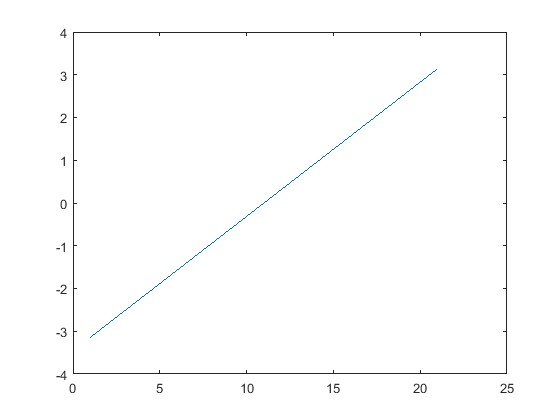

  %reports error in live script but gives correct output
  %in matlab workbench
      eqna = @(x)isequal(x,'N/A');
      setloc = @(x) char((x) .* 'Sea ' + ~(x) .* 'Land'); %setloc takes as input true or false
      hurrs3.Location=cellfun(eqna,hurrs3.Country); %the output hurrs2.Location is an array so use array function next
      hurrs3.Location=arrayfun(setloc,hurrs3.Location,'UniformOutput',false);

Categorical Data

  % convert country and location to categories
  hurrs3.Country=categorical(hurrs3.Country);

hurrs = 51×5 table
    Number         Timestamp              Country        Windspeed    Pressure
    ______    ____________________    _______________    _________    ________

    1         29-Jun-1991 12:00:00    'N/A'               23          1012    
    1         29-Jun-1991 18:00:00    'N/A'               23          1012    
    1         30-Jun-1991 00:00:00    'N/A'              NaN          1012    
    1         30-Jun-1991 06:00:00    'United States'     23          1012    
    1         30-Jun-1991 12:00:00    'United States'     23          1012    
    1         30-Jun-1991 18:00:00    'N/A'               23          1012    
    1         01-Jul-1991 00:00:00    'N/A'               23          1012    
    1         01-Jul-1991 06:00:00    'United States'     23          1012    
    1         01-Jul

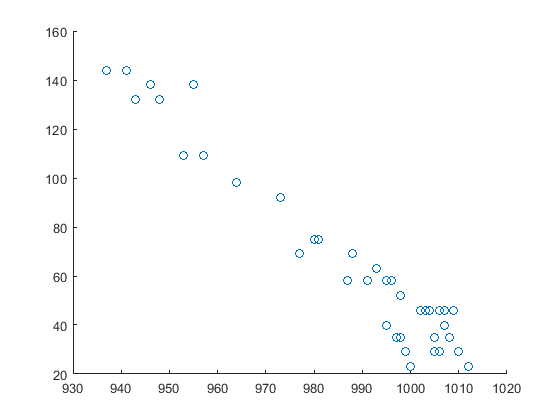

  % hurrs3.Location=categorical(hurrs3.Location);

   

C = hurrs3.Country;

hurrs2 = 51×5 table
    Number         Timestamp              Country        Windspeed    Pressure
    ______    ____________________    _______________    _________    ________

    1         29-Jun-1991 12:00:00    'N/A'               23          1012    
    1         29-Jun-1991 18:00:00    'N/A'               23          1012    
    1         30-Jun-1991 00:00:00    'N/A'              NaN          1012    
    1         30-Jun-1991 06:00:00    'United States'     23          1012    
    1         30-Jun-1991 12:00:00    'United States'     23          1012    
    1         30-Jun-1991 18:00:00    'N/A'               23          1012    
    1         01-Jul-1991 00:00:00    'N/A'               23          1012    
    1         01-Jul-1991 06:00:00    'United States'     23          1012    
    1         01-Ju

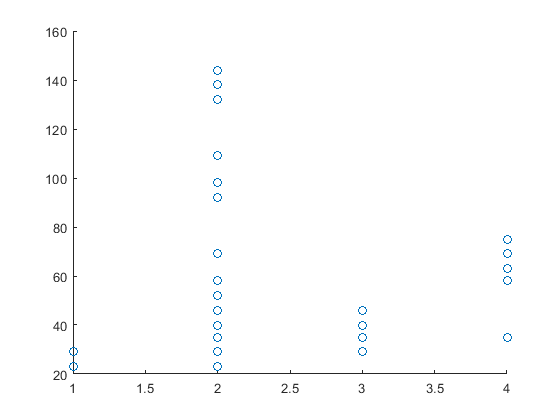

whos C


% convert C to a categorical array

C = categorical(C);


hurrs3 = 51×5 table
    Number         Timestamp              Country        Windspeed    Pressure
    ______    ____________________    _______________    _________    ________

    1         29-Jun-1991 12:00:00    'N/A'               23          1012    
    1         29-Jun-1991 18:00:00    'N/A'               23          1012    
    1         30-Jun-1991 00:00:00    'N/A'              NaN          1012    
    1         30-Jun-1991 06:00:00    'United States'     23          1012    
    1         30-Jun-1991 12:00:00    'United States'     23          1012    
    1         30-Jun-1991 18:00:00    'N/A'               23          1012    
    1         01-Jul-1991 00:00:00    'N/A'               23          1012    
    1         01-Jul-1991 06:00:00    'United States'     23          1012    
    1         NaT  

whos C


%hurrs3.Country
  
 

hurrs3 = 51×5 table
    Number         Timestamp              Country        Windspeed    Pressure
    ______    ____________________    _______________    _________    ________

    1         29-Jun-1991 12:00:00    'N/A'               23          1012    
    1         29-Jun-1991 18:00:00    'N/A'               23          1012    
    1         30-Jun-1991 00:00:00    'N/A'              NaN          1012    
    1         30-Jun-1991 06:00:00    'United States'     23          1012    
    1         30-Jun-1991 12:00:00    'United States'     23          1012    
    1         30-Jun-1991 18:00:00    'N/A'               23          1012    
    1         01-Jul-1991 00:00:00    'N/A'               23          1012    
    1         01-Jul-1991 06:00:00    'United States'     23          1012    
    1         NaT  

rename categories

add a new variable named `Location` to the table `data`. This variable is meant to indicate whether the hurricane was observed on land or on the sea.

One way to do this is to find all the valid country names (values excluding 'N/A') and then merge them to create a new category named `'Land'` using the function `mergecats`. Assign the result to a new variable `Location`in the table `data`.

Then, use the function `renamecats` to rename the category `'N/A'` to `'Sea'`

.

% % % hurrs3=readtable('..\data\hurricaneData1990s-v3.txt','CommentStyle','##')
% 
% 
% % Find the distinct categories
% cats = categories(hurrs3.Country);
% 
% % Remove 'N/A' from cats
% countryNames = setdiff(cats,'N/A');
% 
% % Merge all countries
% hurrs3.Location = mergecats(hurrs3.Country,countryNames,'Land')
% 
% % Rename N/A to Sea
% hurrs3.Location = renamecats(hurrs3.Location,'N/A','Sea') 

create a scatter plot with wind speed values along the x-axis and pressure values along the y-axis. Also, the observations on land should be plotted using red markers and the observations on sea should have blue markers. The plot should look something like this:

You can follow these steps to create the plot.

1. Find the wind speed and pressure values observed on land using the result of `data.Location` `==` `'Land'`as an index. Similarly, find values observed on the sea.

2. Use the `scatter``(``x``,``y``,``'b'``,``'filled'``)` command to create a scatter plot with filled blue markers. Replace `x`and `y` with windspeed and pressure values observed on the sea.

3. Use the command `hold` `on` so that the next plot is added on top of the existing plot.

4. Finally, create another scatter plot with values on land. Make this plot red (`'r'`). Enter `hold` `off` at the end.

% Read data
data = readtable('..\data\hurricaneData1990s-v2.txt','HeaderLines',5);
data.Country = categorical(data.Country);

% TODO - Add a new variable named 'Location' to the table 'data'
% It should be categorical  and have a value 'Land' if the row has a valid
% country listed and 'N/A' otherwise.

% Find the distinct categories
cats = categories(data.Country);

% Remove 'N/A' from cats
countryNames = setdiff(cats,'N/A');


  Name       Size            Bytes  Class          Attributes

  C         51x1               553  categorical              



% Merge all countries
data.Location = mergecats(data.Country,countryNames,'Land');

% Rename N/A to Sea
data.Location = renamecats(data.Location,'N/A','Sea')


  Name       Size            Bytes  Class          Attributes

  C         51x1               553  categorical              



% Find index of on-land and on-sea observation index
onland = data.Location == 'Land';
onsea = data.Location == 'Sea';

% Create scatter plots
scatter(data.Windspeed(onsea),data.Pressure(onsea),'b','filled');
hold on
scatter(data.Windspeed(onland),data.Pressure(onland),'r','filled');
hold off

% Optional - annotate the plot
xlabel('Wind Speed')
ylabel('Pressure')
legend('Sea','Land')




using categorical values

**Info:** If your categories have an inherent ordering – for example, “low”, “medium”, and “high” – you can specify this with an optional property `'Ordinal'`:

v = [ 10 5 0 0 ];
levels = { 'beg' 'mid' 'last' };
categorical(v,[0 5 10],levels)

x = [2 4 1 1 2 2 1 2 4];
xlevels = {'tiny','small','big','huge'};
y = categorical(x,1:4,xlevels)


%ordinal values

v = [ 10 5 0 0 ];
levels = { 'beg' 'mid' 'last' };
c = categorical(v,...
    [0 5 10],levels,...
    'Ordinal',true)
 c > 'mid'
 

data = 51×6 table
    Number         Timestamp             Country       Windspeed    Pressure    Location
    ______    ____________________    _____________    _________    ________    ________

    1         29-Jun-1991 12:00:00    N/A               23          1012        Sea     
    1         29-Jun-1991 18:00:00    N/A               23          1012        Sea     
    1         30-Jun-1991 00:00:00    N/A              NaN          1012        Sea     
    1         30-Jun-1991 06:00:00    United States     23          1012        Land    
    1         30-Jun-1991 12:00:00    United States     23          1012        Land    
    1         30-Jun-1991 18:00:00    N/A               23          1012        Sea     
    1         01-Jul-1991 00:00:00    N/A               23       

 y = categorical(x,1:4,xlevels,'Ordinal',true)
 
 %Info: Categorical arrays allow the use of == for comparison.
y == 'tiny';

%Create a variable named iSmall which contains values of true 
% corresponding to the values in y that equal 'small'.

iSmall = y == 'small'

% Create a variable named idx which contains values 
% of true corresponding to the values in y that are larger than tiny.
idx = y > 'tiny'

Working with missing data

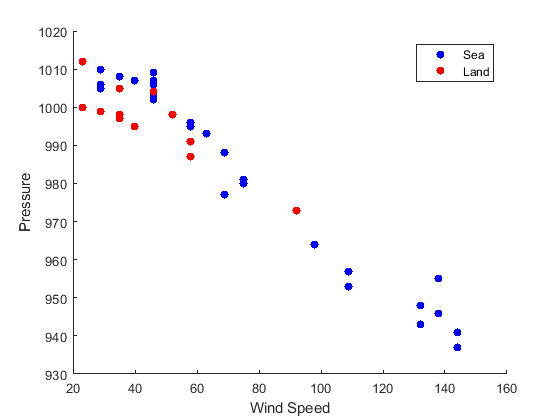

x = [0.32 0.95 NaN 0.87 0.71 0.42]


xAvg = mean(x)

% Info: In order to find the average value of a vector and omit NaN from the calculation,
% you can use the 'omitnan' flag as an additional input to the mean function.

xAvg = mean(x,'omitnan')
xMed = median(x,'omitnan')

% Info: There are some statistical functions, such as max and min, 
% that are designed to ignore NaNs in calculations by default.

ans = 1×4 categorical array
     last      mid      beg      beg 


xMin = min(x)
y=x
test = isequal(x,y)


y = 1×9 categorical array
     small      huge      tiny      tiny      small      small      tiny      small      huge 


% Info: The isequal function tests for strict equality, which means that NaNs
% will cause it to fail. However, if you wish to test an array for numeric equality,
%     as well as determining if the NaNs align, you can use isequaln.
test = isequaln(x,y)

The default behavior for many statistical functions is that `NaN` will be returned if the array includes `NaN`:

- [`cov`](http://www.mathworks.com/help/matlab/ref/cov.html)

- [`mean`](http://www.mathworks.com/help/matlab/ref/mean.html)

- [`median`](http://www.mathworks.com/help/matlab/ref/median.html)

- [`std`](http://www.mathworks.com/help/matlab/ref/std.html)

- [`var`](http://www.mathworks.com/help/matlab/ref/var.html)

However, the default behavior of [`max`](http://www.mathworks.com/help/matlab/ref/max.html) and [`min`](http://www.mathworks.com/help/matlab/ref/min.html) is to use `'omitnan'`.

zero values update

wsI=isnan(hurrs3.Windspeed);   
hurrs3.Windspeed(find(wsI))=0;

% sz=size(hurrs3);
%   a=hurrs3.Country;

c = 1×4 categorical array
     last      mid      beg      beg 


%   for i=1:sz(1)

ans = 1×4 logical array
   1   0   0   0


%       if isequal(a{i},'N/A' )
%           hurrs3.Location{i} = 'Sea';

y = 1×9 categorical array
     small      huge      tiny      tiny      small      small      tiny      small      huge 


%       else
%           hurrs3.Location{i} = 'Land';
%       end
%   end

## Discretizing Continuous Data

discretize the values in `price` into 4 bins.

As a first step, create a row vector, `levels`, that contains the edge values of the desired bins. The lowest edge value should be `0`, the highest should be `40` and difference between the adjacent edge values should be `10`

price = [34.17,26.71,7.92,27.17,36.30,24.88,30.34,27.26,16.96];

iSmall = 1×9 logical array
   1   0   0   0   1   1   0   1   0


levels = 0:10:40

% Info: You can use the discretize function to categorize
% values into discrete bins using the values of the bin edges.

idx = 1×9 logical array
   1   1   0   0   1   1   0   1   1


% Bin the values in the price vector using levels as the 
% bin edges. Store the resulting bin numbers in pBinNo.
pBinNo = discretize(price,levels)

x =     0.3200    0.9500       NaN    0.8700    0.7100    0.4200



% Discretize x using the bin edges binedges 

xAvg = NaN

% and store the resulting bin numbers in y.
binedges = [0 0.2 0.6 0.9];
x = [ 0.90 0.32 0.95 NaN 0.87 0.71 0.42 0.60];
y = discretize(x,binedges)


xAvg = 0.6540

% Info: Any NaNs or values outside the range of the bins

xMed = 0.7100

% are unclassified.
% 
% If you want to include bins for values outside of the edges, 
% add -Inf or Inf to the vector of bin edges.

xMin = 0.3200

% Update binedges so that there is one more category that extends 

y =     0.3200    0.9500       NaN    0.8700    0.7100    0.4200


% the range to infinity.

test = logical
   0



binedges = [0 0.2 0.6 0.9 Inf]

% create a variable named y which contains the bin number
% for each value in x.

test = logical
   1


y = discretize(x,binedges)

% Info: By default, the bins are returned as numeric values.
% To discretize data into categories, use the Categorical option.
binedges = [0 0.2 0.6 0.9 Inf];
x = [ 0.90 0.32 0.95 NaN 0.87 0.71 0.42 0.60];
cnm = {'red','green','blue','black'};

y = discretize(x,binedges,'Categorical',cnm)


% Info: Because the categories are based on a numeric scale, 
% the resulting categorical array is ordinal. Thus, one category 
% can be greater than another.
% Now create a variable named leGreen that contains the number of 
% values in y that are less than or equal to 'green'.
leGreen = nnz(y <= 'green')

## Discretizing the hurricane data

**Info:** The Saffir-Simpson hurricane scale bin edges are stored in `SSscale`. Each bin corresponds to a hurricane category identified by the `catnames`variable.

% create a new variable named data.HurrCat that contains the 
% hurricane category of the observation based on data.Windspeed.
SSscale = [0 39 74 96 111 130 157 Inf];
catnames = {'TD','TS','1','2','3','4','5'};

levels =      0    10    20    30    40


data.HurrCat = discretize(data.Windspeed,SSscale,'Categorical',catnames)


pBinNo =      4     3     1     3     4     3     4     3     2


y =      3     2   NaN   NaN     3     3     2     3


binedges =          0    0.2000    0.6000    0.9000       Inf


y =      4     2     4   NaN     3     3     2     3


y = 1×8 categorical array
     black      green      black      <undefined>      blue      blue      green      blue 


leGreen = 2

data = 51×7 table
    Number         Timestamp             Country       Windspeed    Pressure    Location      HurrCat  
    ______    ____________________    _____________    _________    ________    ________    ___________

    1         29-Jun-1991 12:00:00    N/A               23          1012        Sea         TD         
    1         29-Jun-1991 18:00:00    N/A               23          1012        Sea         TD         
    1         30-Jun-1991 00:00:00    N/A              NaN          1012        Sea         <undefined>
    1         30-Jun-1991 06:00:00    United States     23          1012        Land        TD         
    1         30-Jun-1991 12:00:00    United States     23          1012        Land        TD         
    1         3